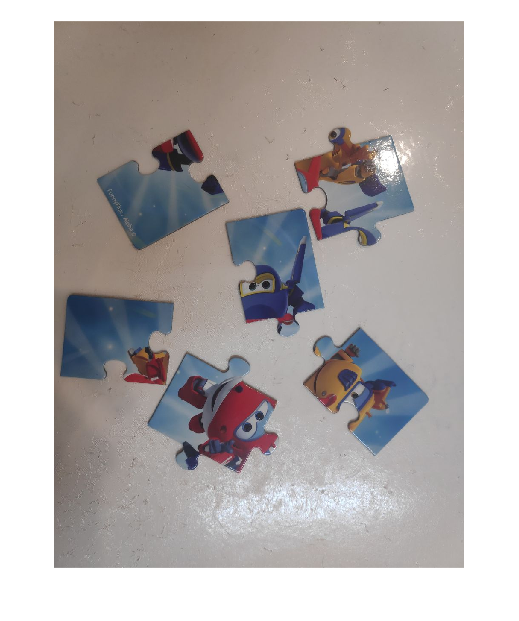

RGB=imread("img\pzl_6_2.jpg");
imshow(RGB)

% RGB = imread('kobi.png');
% RGB=imresize(RGB,0.1);

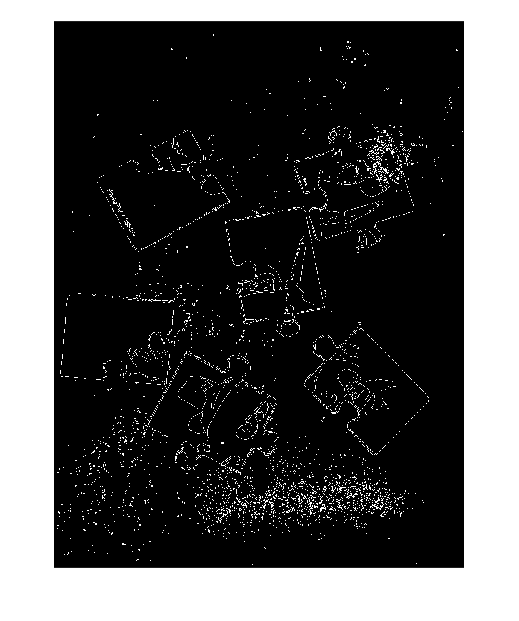

img=dip_GN_imread("img\pzl_6_2.jpg");
BW=edge(img,"prewitt","thinning");
imshow(BW)

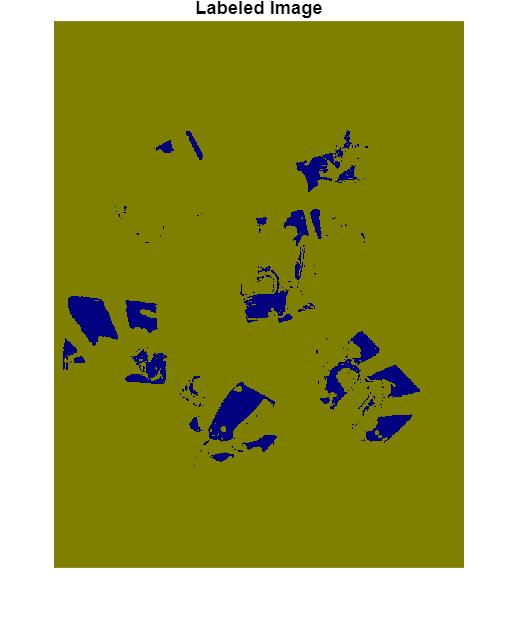

[H, S ,V]=rgb2hsv(RGB);
S=uint8(S);
L = imsegkmeans(S,2);
B = labeloverlay(S,L);
imshow(B)
title('Labeled Image')

wavelength = 2.^(0:5) * 3;
orientation = 0:45:135;
g = gabor(wavelength,orientation);

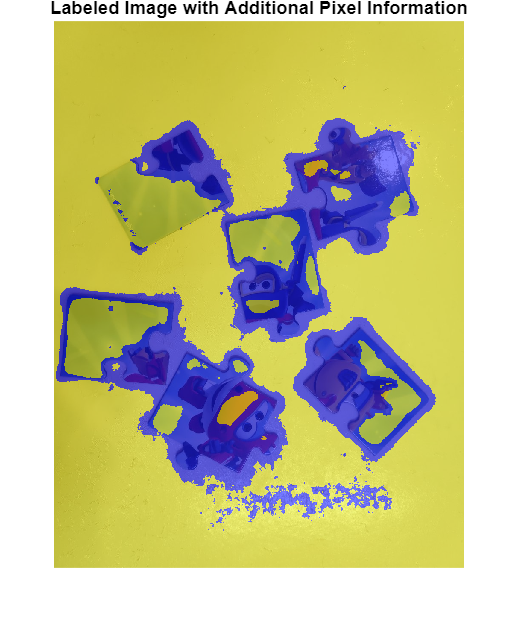

I = im2gray(im2single(RGB));
gabormag = imgaborfilt(I,g);
% montage(gabormag,'Size',[4 6])
nrows = size(RGB,1);
ncols = size(RGB,2);
[X,Y] = meshgrid(1:ncols,1:nrows);
featureSet = cat(3,I,gabormag,X,Y);

L2 = imsegkmeans(featureSet,2,'NormalizeInput',true);
C = labeloverlay(RGB,L2);
imshow(C)
title('Labeled Image with Additional Pixel Information')